clc
clearvars
close all

nlist = readtable("./data/nlist.csv");
nlist.Properties.VariableNames = {'Name','Label','Group'};
nlist.Name = string(nlist.Name);
elist_dy = readtable("./data/elist_dynamic.csv");

node_cdata = NaN(size(nlist,1),3);
node_group = unique(nlist.Group);
ccode = NaN(length(node_group),3);
ccode(1,:) = [1, 0, 0];
ccode(2,:) = [0, 0, 1];
for i=1:length(node_group)
    idx = find(strcmp(nlist.Group, node_group{i}));
    node_cdata(idx,:) = repmat(ccode(i,:),length(idx),1);
end

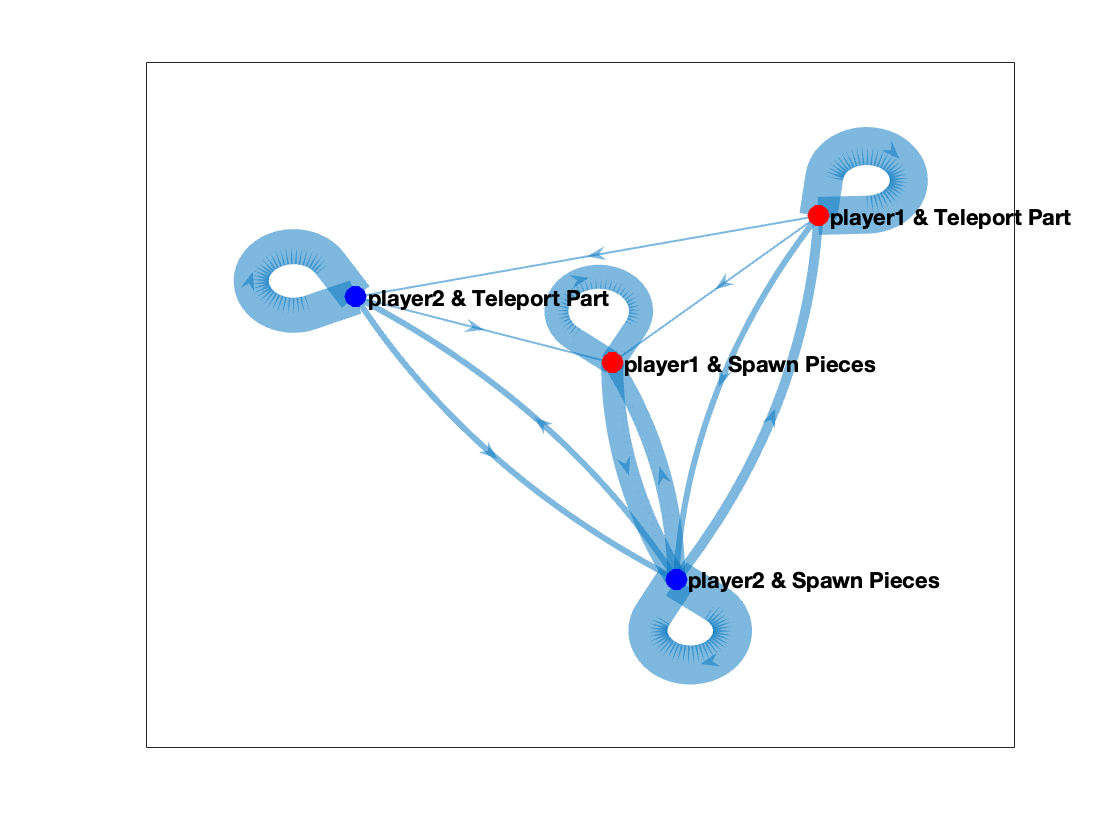

ans =     0.1380
    0.3348
    0.1925
    0.3348


num_edges = size(elist_dy,1);
snodes = elist_dy.Source;
tnodes = elist_dy.Target;
edge_weight_cutoff = 16;

s = snodes(1);
t = tnodes(1);
elist = [s,t];
w = 1;
etable = table(elist,w, 'VariableNames',{'EndNodes','Weight'});
G = digraph(etable,nlist);

figure('Color','w')
for i=2:num_edges
    s = snodes(i);
    t = tnodes(i);
    [edge_exist,update_idx] = ismember([s,t],str2double(G.Edges.EndNodes),'rows');

    if(all(edge_exist))
        w = G.Edges.Weight;
        if(w(update_idx) >= edge_weight_cutoff)
            G.Edges.Weight(update_idx) = w(update_idx) + (0.5)^(w(update_idx)-edge_weight_cutoff+1);
        else
            G.Edges.Weight(update_idx) = w(update_idx)+1;
        end
    else
        G = addedge(G,num2str(s),num2str(t),1);
    end
    
    plot(G,'NodeLabel',nlist.Label,'NodeColor',node_cdata,'MarkerSize',10,...
        'NodeFontSize',11,'NodeFontWeight','bold',...
        'LineWidth',G.Edges.Weight,'Layout','force')
    drawnow
end